# BRIDGE O DOOOOM

Plotting the path

beta = 0.2

beta = 0.2000

points = linspace(0, 3.2, 1000);
x = 0.3960 * cos(2.65*(1.4 + points));
y = -0.99 * sin(1.4 + points);
syms u r t

u = beta * t

$$u = \frac{t}{5}$$

r_i = 0.3960 * cos(2.65*(1.4 + u))

$$r\_i = \frac{99\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{250}$$

r_j = -0.99 * sin(1.4 + u)

$$r\_j = -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{100}$$

r_k = 0 * u

$$r\_k = 0$$

assume(t,'real')
r = [r_i, r_j, r_k];
drdu = diff(r,t);
T_hat = simplify(drdu./norm(drdu))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$

dT_hatdu=diff(T_hat,t);
N_hat=dT_hatdu/norm(dT_hatdu);
N_hat=simplify(N_hat);

vecs = transpose(linspace(0.5, 3, 3));
vecs_x = 0.3960 * cos(2.65*(1.4 + vecs));
vecs_y = -0.99 * sin(1.4 + vecs);
N = eval(subs(N_hat,vecs/beta))

N =    -0.3061    0.9520         0
    0.7310    0.6824         0
    0.3456   -0.9384         0


T = eval(subs(T_hat, vecs/beta))

T =     0.9520    0.3061         0
   -0.6824    0.7310         0
    0.9384    0.3456         0


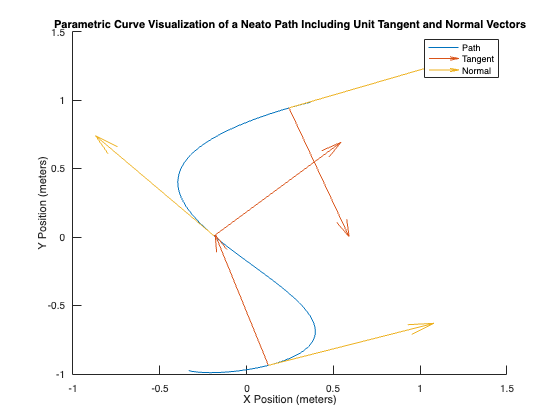

f = figure();
hold on
plot(x,y)
title('Parametric Curve Visualization of a Neato Path Including Unit Tangent and Normal Vectors')
xlabel('X Position (meters)') 
ylabel('Y Position (meters)') 
quiver(vecs_x, vecs_y, N(:,1), N(:, 2))
quiver(vecs_x, vecs_y, T(:,1), T(:, 2))
legend("Path","Tangent","Normal")

Plotting the velocities

vel = diff(r, t)

$$vel = \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{25000} & -\frac{99\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{500} & 0 \end{array}\right)$$

diff(T_hat)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}} & \frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sigma_{1}}{{\sigma_{2}}^{3/2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right) \end{array}$$

omega = cross(T_hat, diff(T_hat))

$$omega = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{50\,\sigma_{4}\,\left(\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}+\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\left(\frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\sigma_{4}\,\sigma_{1}}{{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\sigma_{4}\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\sigma_{4}}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)\\ \sigma_{4}=\cos\left(\frac{t}{5}+\frac{7}{5}\right) \end{array}$$

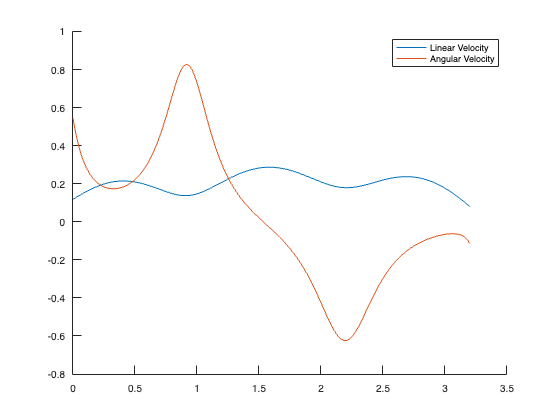

V_n = (eval(subs(vel, transpose(points)/beta)));
V_n = sqrt(sum(V_n.^2,2));
ang_vel = eval(subs(omega, transpose(points)/beta));
figure;
hold on
plot(points, V_n)
plot(points, ang_vel(:, 3))
legend("Linear Velocity", "Angular Velocity")

Left Right Velocities

V_L = V_n - ang_vel(:, 3) * 0.245/2

V_L =     0.0512
    0.0540
    0.0567
    0.0594
    0.0621
    0.0647
    0.0672
    0.0698
    0.0722
    0.0747


V_R = V_n + ang_vel(:, 3) * 0.245/2

V_R =     0.1846
    0.1843
    0.1841
    0.1839
    0.1838
    0.1837
    0.1837
    0.1837
    0.1837
    0.1838


% Initial setup
drivetime = 0.2; % s for each velocity pair

% Assuming V_L and V_R are your vectors of length 1000
new_length = 1000 / 10; % Target length after averaging

% Data collection storage space initialization
max_points = new_length;
encoder_data = zeros(max_points, 3);
iter = 0;

% Reshape and average V_L
V_L_reshaped = reshape(V_L, [10, new_length]);

Unrecognized function or variable 'V_L'.

V_L_short = mean(V_L_reshaped, 1);

% Reshape and average V_R
V_R_reshaped = reshape(V_R, [10, new_length]);
V_R_short = mean(V_R_reshaped, 1);

% Initialize connection with the Neato robot
try
    [sensors, vels] = neato('192.168.16.67'); % Adjust IP address as necessary
catch
    error('Failed to connect to Neato robot. Please check the IP address and network connection.');
end
fig = gcf;

% Start after setup verification
disp('Setup complete. Press enter to start.');

% Main loop for controlling the Neato robot based on averaged velocity vectors
for idx = 1:length(V_L_short)
    vl = V_L_short(idx);
    vr = V_R_short(idx);
    disp(['Running with vl = ', num2str(vl), ' and vr = ', num2str(vr)]);
    tic;
    t = toc;
    
    while t < drivetime
        iter = iter + 1;
        if iter <= max_points
            % Ensure sensors.encoders data is valid before accessing
            if isfield(sensors, 'encoders') && length(sensors.encoders) >= 2
                encoder_data(iter, :) = [t, sensors.encoders(1), sensors.encoders(2)];
            else
                disp('Warning: Encoder data not available.');
            end
        end
        t = toc; % Update time variable
        vels.lrWheelVelocitiesInMetersPerSecond = [vl, vr];
    end
    
    % Stop the robot after each iteration
    vels.lrWheelVelocitiesInMetersPerSecond = [0, 0];
end

% Clean up
close(fig); % Close the figure at the end of all iterations
disp('Data collection complete.');

% Optional: Additional code to process or visualize the collected data

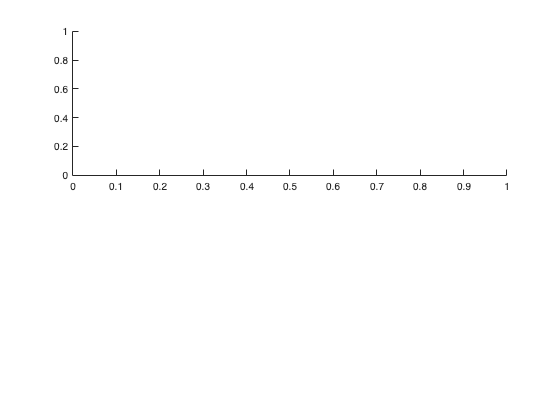

% Parameters
wheel_base = 0.245; % Distance between the wheels in meters

% Initialization
x_pos = 0; % Initial x position
y_pos = 0; % Initial y position
theta = 0; % Initial orientation angle in radians

% Calculate measured linear speed and angular velocity
measured_linear_speeds = zeros(max_points-1, 1);
measured_angular_velocities = zeros(max_points-1, 1);

for i = 2:max_points
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2));
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3));
    delta_time = drivetime; % Assuming constant drive time between measurements
    
    % Linear speed is the average of the left and right wheel speeds
    measured_linear_speeds(i-1) = (delta_left + delta_right) / (2 * delta_time);
    
    % Angular velocity is the difference in wheel speeds divided by the wheelbase, considering the direction
    measured_angular_velocities(i-1) = (delta_right - delta_left) / (wheel_base * delta_time);
end

% Time array for plotting
time_array = (1:max_points-1) * drivetime;


% Plot Linear Speed
subplot(2, 1, 1); % Two rows, one column, first subplot
hold on;

plot(time_array, planned_linear_speeds, 'LineWidth', 2); % Planned linear speed in solid line

Unrecognized function or variable 'planned_linear_speeds'.

plot(time_array, measured_linear_speeds, '--', 'LineWidth', 2); % Measured linear speed in dashed line
title('Linear Speed Over Time');
xlabel('Time (s)');
ylabel('Linear Speed (m/s)');
legend('Planned Linear Speed', 'Measured Linear Speed');
hold off;

% Plot Angular Velocity
subplot(2, 1, 2); % Two rows, one column, second subplot
hold on;
plot(time_array, planned_angular_velocities, 'LineWidth', 2); % Planned angular velocity in solid line
plot(time_array, measured_angular_velocities, '--', 'LineWidth', 2); % Measured angular velocity in dashed line
title('Angular Velocity Over Time');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
legend('Planned Angular Velocity', 'Measured Angular Velocity');
hold off;

% Assuming wheel_radius and encoder_resolution are defined as before
% Calculate measured left and right wheel velocities from encoder data
measured_V_L = zeros(max_points-1, 1);
measured_V_R = zeros(max_points-1, 1);

for i = 2:max_points
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2)) / encoder_resolution * (2*pi*wheel_radius);
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3)) / encoder_resolution * (2*pi*wheel_radius);
    delta_time = drivetime; % Time interval between measurements
    
    % Wheel velocities in meters per second
    measured_V_L(i-1) = delta_left / delta_time;
    measured_V_R(i-1) = delta_right / delta_time;
end


% Plotting
figure; % Start a new figure
hold on; % Hold on for multiple plots

% Theoretical Left Wheel Velocity
plot(time_array, V_L_short, 'LineWidth', 2, 'DisplayName', 'Theoretical Left Wheel Velocity');

% Measured Left Wheel Velocity
plot(time_array, measured_V_L, '--', 'LineWidth', 2, 'DisplayName', 'Measured Left Wheel Velocity');

% Theoretical Right Wheel Velocity
plot(time_array, V_R_short, 'LineWidth', 2, 'DisplayName', 'Theoretical Right Wheel Velocity');

% Measured Right Wheel Velocity
plot(time_array, measured_V_R, '--', 'LineWidth', 2, 'DisplayName', 'Measured Right Wheel Velocity');

% Configure the plot
title('Wheel Velocities Over Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend('show');
grid on;
hold off;

% TODO: Adding a caption

% Storage for position and orientation
x_trajectory = zeros(max_points, 1);

Unrecognized function or variable 'max_points'.

y_trajectory = zeros(max_points, 1);
theta_trajectory = zeros(max_points, 1);

% Calculate the trajectory
for i = 2:max_points
    % Calculate the distance each wheel traveled in meters
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2));
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3));
    
    % Avg distance traveled
    delta_center = (delta_left + delta_right) / 2;
    
    % Change in orientation
    delta_theta = (delta_right - delta_left) / wheel_base;
    
    % Update orientation
    theta = theta + delta_theta;
    
    % Update position
    x_pos = x_pos + delta_center * cos(theta);
    y_pos = y_pos + delta_center * sin(theta);
    
    % Store trajectory
    x_trajectory(i) = x_pos;
    y_trajectory(i) = y_pos;
    theta_trajectory(i) = theta;
end

% Assuming x_trajectory, y_trajectory, x, y, vecs_x, vecs_y, N, and T are
% already calculated (code block 2)

% Start new figure
figure;
hold on; % Hold on to plot multiple graphs in the same figure

% Plot robot path according to sensor information
plot(x_trajectory, y_trajectory, ':', 'LineWidth', 2);

% Plot original parametric curve
plot(x, y);

% Add quivers for unit tangent and normal vectors at specified points
quiver(vecs_x, vecs_y, N(:,1), N(:, 2), 'AutoScale', 'off');
quiver(vecs_x, vecs_y, T(:,1), T(:, 2), 'AutoScale', 'off');

% Configure the plot
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Combined Visualization of Robot Path and Parametric Curve with Tangent and Normal Vectors');
legend('Sensor-based Path', 'Parametric Path', 'Normal Vectors', 'Tangent Vectors');
axis equal;
grid on;

% Release the hold
hold off;
